# Sensor Calibration

### Data Collection:

Position the ball along the tube by putting a pencil or piece of wire through a hole of the

tube and rest the ping pong ball on top of it. Do this for each hole one at a time. Start from the

hole nearest to the sensor. Write a MATLAB program in order to:

1--Prompt the user to position the ball. Use the command pause and then press the space bar to

continue when ready.

2--Collect N = 3 measurements at each position of ball. There are M = 15 positions.

3--Store the data to an array.

Open port to Pico

clear s % closes ports already open
s = serialport('COM4',9600) % Check COM#

s =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


sensor = zeros(14,3); % initialize empy array for sensor values

% loop through rows in sensor array
for m = 1:size(sensor,1)
    fprintf("Please position the ball to hole: #" + m + "\n") % prompt user to position ball
    pause % wait until user keyboard input
    % loop through columns in sensor array
    for n = 1:size(sensor,2)
        s.writeline("read") % write "read" to Pico
        sensor(m,n) = s.readline(); % read ADC value from Pico
        pause(1) % wait 1 second
    end
end

Please position the ball to hole: #1
Please position the ball to hole: #2
Please position the ball to hole: #3
Please position the ball to hole: #4
Please position the ball to hole: #5
Please position the ball to hole: #6
Please position the ball to hole: #7
Please position the ball to hole: #8
Please position the ball to hole: #9
Please position the ball to hole: #10
Please position the ball to hole: #11
Please position the ball to hole: #12
Please position the ball to hole: #13
Please position the ball to hole: #14


4--Save the collected data in a file called sensor_calibration_DATE.mat

save sensor_calibration_04_05_2024.mat sensor

load sensor_calibration_03_05_2024.mat
sensor

sensor =        17092       17540       17620
       24998       24982       29991
       39785       39561       45355
       35432       35464       35880
       36616       31529       30679
       27158       27494       27238
       24838       24918       24630
       22597       22629       22677
       21285       21797       21221
       19508       19732       21733


5--Plot sensor output vs. hole number. Use markers; include axis labels, legend, and title.

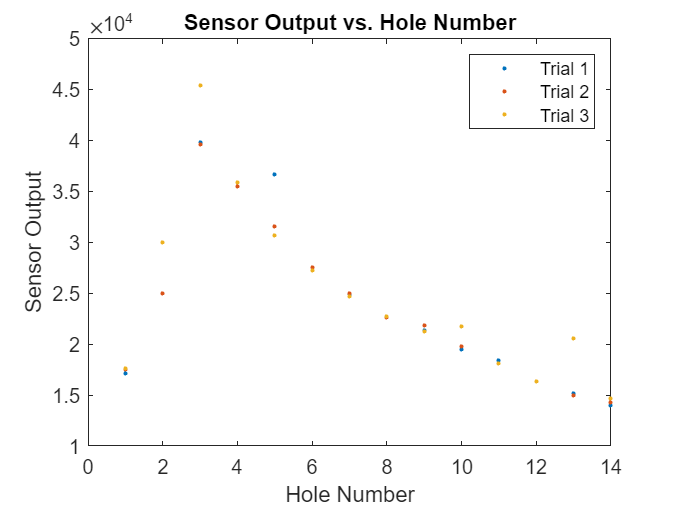

plot(sensor, ".") % plot sensor data
title("Sensor Output vs. Hole Number")
xlabel("Hole Number")
ylabel("Sensor Output")
legend("Trial 1", "Trial 2", "Trial 3")

Discuss the output vs. position contour. Is it linear, parabolic, or other? Are there any outliers in

the measurements?

It's linear up to a point. When it gets really close to the sensor, the sensor output drops drastically. There are a few outliers in the measurements amongnst the multipule trials. 

### Sensor Calibration:

Having collected the data this step performs sensor calibration. A mathematical

relationship between ADC output voltage, V, and ball position, D, is sought. The simplest

relationship is linear:

V = a ∙ D + b

Based on the theory developed in Lecture Notes #2, identify a range on the horizontal where the

markers seem to follow a linear trend (e.g., form holes #6 to #15). In MATLAB, do the

following:

1--For each position in the selected range find the mean value of the N = 3 measurements taken.

average = trimmean(sensor,50,2); % take a 50% trimmed mean to remove bias from outliers
hole_range = (7:14); % index for range of holes to find linear trend
V = average(hole_range) % index average array using range of holes

V =        24838
       22629
       21285
       19732
       18068
       16307
       15123
       14227


2--Use the pseudo-inverse method to solve for the parameters a and b of the best line fit to all

points in the selected interval.

D_2 = ones(size(V)); % create a column vector of ones with size of V
D = [hole_range' D_2] % create D matrix [D_1 1]

D =      7     1
     8     1
     9     1
    10     1
    11     1
    12     1
    13     1
    14     1


P = inv(D'*D) * D' * V; % pseudo-inverse to solve for the parameters
a = P(1)

a = -1.5286e+03

b = P(2)

b = 3.5077e+04

3--Using the calculated values for parameters a and b plot the best line fit inside the selected

range and overlay the markers of the experimental measurements.

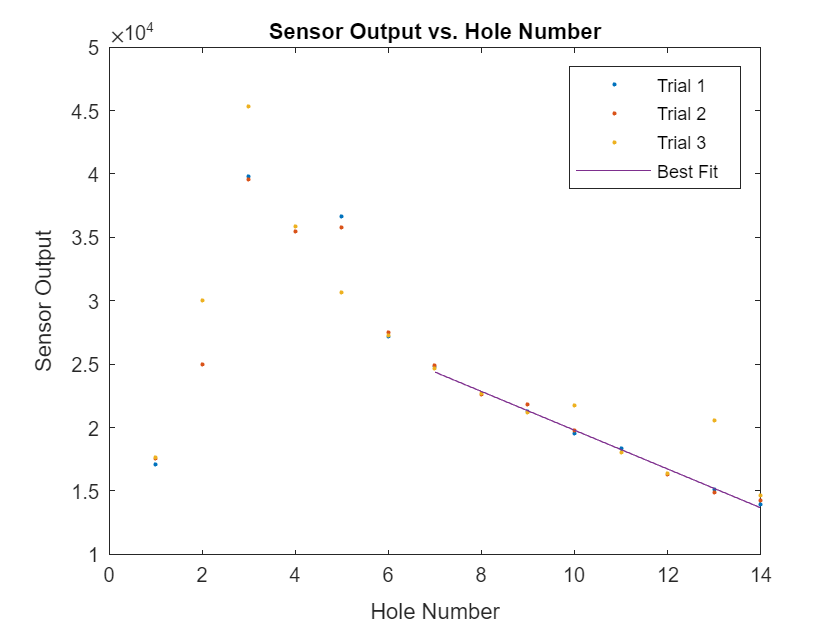

x = hole_range; % x axis range is same as hole_range
y = a*x + b; % calculate line using calculated parameters

plot(sensor, ".") % plot sensor data

hold on
plot(x,y) % plot best fit line
hold off

title("Sensor Output vs. Hole Number")
xlabel("Hole Number")
ylabel("Sensor Output")
legend("Trial 1", "Trial 2", "Trial 3", "Best Fit")

Discuss whether the line passes closely from the markers inside the selected interval.

The line passes very closely with the markers inside the selected interval!

### Inverse Linear Relationship:

For the purpose of closed-loop ball levitation, the position of the ball corresponding to

the sensor output is needed. Find the parameters c and e of the inverse linear relationship:

D = c ∙ V + e

format long % formatted to long for best accuracy
% caluculate inverse linear relationship parameters using algebra
c = 1/a

c =     -6.541801331723846e-04


e = -b/a

e =   22.946512986254490
